%HW1
clear

x0 = 5;
n = 10;
a = 3;
m = 150;

[x, xnot] = uni(x0, n, a, m)

x =    0.100000000000000   0.300000000000000   0.900000000000000   0.700000000000000   0.100000000000000   0.300000000000000   0.900000000000000   0.700000000000000   0.100000000000000   0.300000000000000


xnot =     15    45   135   105    15    45   135   105    15    45



n = 10e4;
[x, xnot] = uni(x0, n, a, m)

x =    0.100000000000000   0.300000000000000   0.900000000000000   0.700000000000000   0.100000000000000   0.300000000000000   0.900000000000000   0.700000000000000   0.100000000000000   0.300000000000000   0.900000000000000   0.700000000000000   0.100000000000000   0.300000000000000   0.900000000000000   0.700000000000000   0.100000000000000   0.300000000000000   0.900000000000000   0.700000000000000   0.100000000000000   0.300000000000000   0.900000000000000   0.700000000000000   0.100000000000000   0.300000000000000   0.900000000000000   0.700000000000000   0.100000000000000   0.300000000000000   0.900000000000000   0.700000000000000   0.100000000000000   0.300000000000000   0.900000000000000   0.700000000000000   0.100000000000000   0.300000000000000   0.900000000000000   0.700000000000000   0.100000000000000   0.300000000000000   0.900000000000000   0.700000000000000   0.100000000000000   0.300000000000000   0.900000000000000   0.700000000000000   0.100000000000000   0.30000000000

xnot =     15    45   135   105    15    45   135   105    15    45   135   105    15    45   135   105    15    45   135   105    15    45   135   105    15    45   135   105    15    45   135   105    15    45   135   105    15    45   135   105    15    45   135   105    15    45   135   105    15    45



mean_x = mean(x)

mean_x =    0.500000000000000


var_x = var(x)

var_x =    0.100001000010001


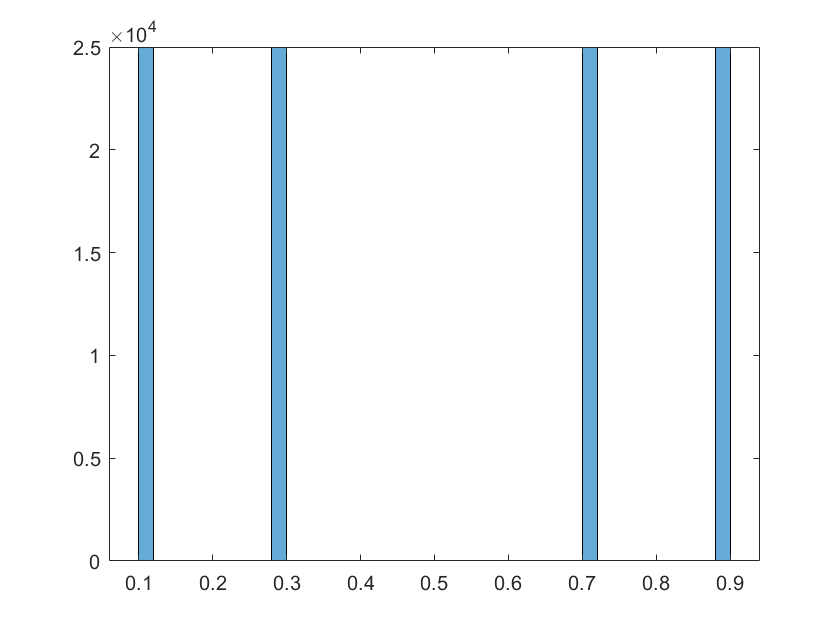

histogram(x)


y = rand(n, 1);
mean_x = mean(y)

mean_x =    0.499411705626541


var_x = var(y)

var_x =    0.083632379724995


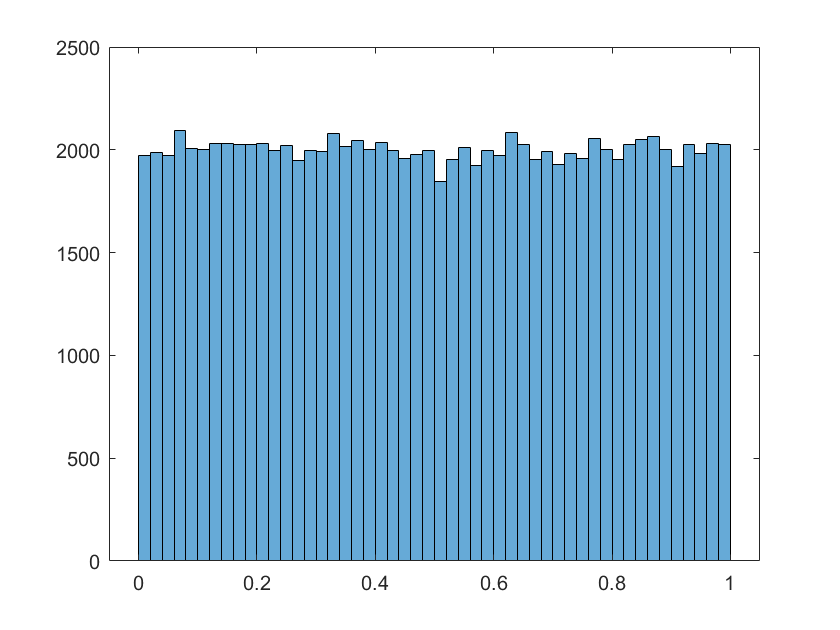

histogram(y)

function [x,xnot] = uni(x0,n,a,m)
    for k = 1:n
        x0 = x0*a;
        x1 = mod(x0,m);
        xn = x1/m;
        x(:,k) = xn;
        xnot(:,k) = x1;
        x0 = x1;
    end
end